**Inizializzazione del programma (12.00)**

clear
clc
close all

## Esercizio 1

a = 0.031;
tau = 0.172;
k = 1;

s = tf('s');

C = k * (1 + tau * s) / (1 + tau * a * s);
P = 1 / s^2;
L = C * P;
W = minreal(feedback(L, 1));
W

W =
 
           32.26 s + 187.5
  ---------------------------------
  s^3 + 187.5 s^2 + 32.26 s + 187.5
 
Continuous-time transfer function.



W(s) è la funzione di trasferimento del sistema in catena chiusa. Ne valuto la risposta al gradino.

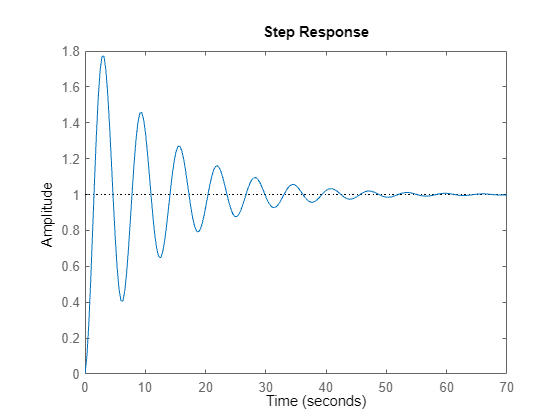

step(W)

Valuto la risposta al gradino considerando il tempo di assestamento al 5%.

stepinfo(W, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 1.0621
    TransientTime: 34.9610
     SettlingTime: 34.9610
      SettlingMin: 0.4063
      SettlingMax: 1.7709
        Overshoot: 77.0924
       Undershoot: 0
             Peak: 1.7709
         PeakTime: 3.1402


Il tempo di assestamento al 5% è t = 34.961 s, mentre la sovraelongazione percentuale è M = 77.0924%.

[Gm, Pm, Wcg, Wcp] = margin(W)

Gm = Inf

Pm = 26.5009

Wcg = Inf

Wcp = 1.4155

Il margine di fase è Pm = 26.5009°, mentre la pulsazione di attraversamento è wcp = 1.4155 rad/s.

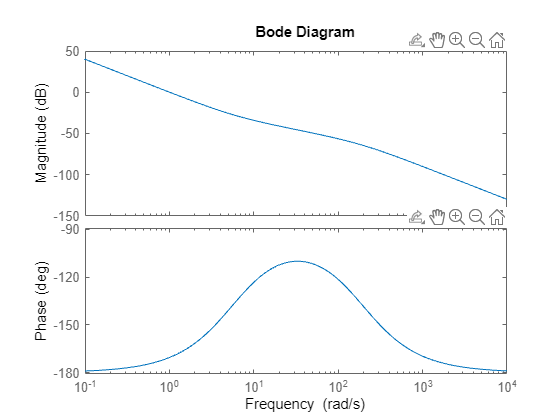

bode(L)

Un margine di fase di 60° si ottiene quando la fase è pari a -120°. In questo caso, si ha per wgc' = 11 rad/s circa.

M = abs(freqresp(L, 11))

M = 0.0177

k1 = 1 / M;
C1 = C * k1; % Posso farlo perché k = 1
L1 = C1 * P;
W1 = minreal(feedback(L1, 1));
W1

W1 =
 
           1827 s + 1.062e04
  -----------------------------------
  s^3 + 187.5 s^2 + 1827 s + 1.062e04
 
Continuous-time transfer function.



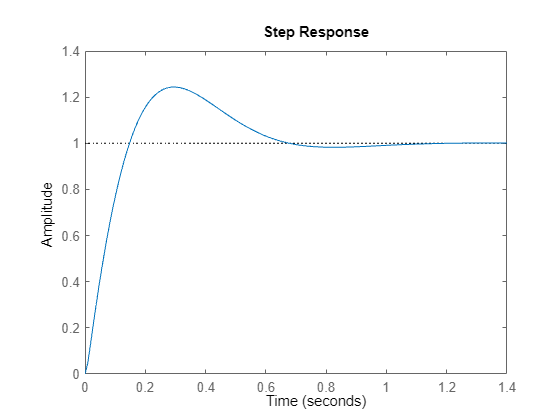

step(W1)

stepinfo(W1, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.1098
    TransientTime: 0.5675
     SettlingTime: 0.5675
      SettlingMin: 0.9229
      SettlingMax: 1.2439
        Overshoot: 24.3881
       Undershoot: 0
             Peak: 1.2439
         PeakTime: 0.2962


Si ottiene un tempo di assestamento t = 0.5675 s e una sovraelongazione percentuale di M = 24.3881%.

12.15

## Esercizio 2

close all
clear
clc

s = tf('s');
mot.k = 5.2;
mot.T = 0.03;
P = mot.k / (s * (mot.T * s + 1));

pid.Kp = 8.7;
pid.Ki = 120;
pid.Kd = 0.16;
pid.Tl = 0.0053;

C = pid.Kp + pid.Ki / s + pid.Kd * s / (pid.Tl * s + 1);

Trovo le tre funzioni di trasferimento cercate.

T1 = minreal(feedback(C * P, 1));
G1 = minreal(feedback(P, C));
W1 = minreal(feedback(C, P));

Valuto le risposte al gradino di ciascun sistema

close all
figure(1)
subplot(3, 1, 1)
step(T1)
subplot(3, 1, 2)
step(G1)
subplot(3, 1, 3)
step(W1)

Considero lo schema di controllo alternativo proposto.

C1 = pid.Kp + pid.Ki / s;
C2 = pid.Kd * s / (pid.Tl * s + 1);

Ricavo le funzioni di trasferimento richieste.

T2 = minreal(P * C1 / (1 + P * (C1 + C2)));
G2 = minreal(P / (1 + P * (C1 + C2)));
W2 = minreal(C1 / (1 + P * (C1 + C2)));

Riporto le riposte al gradino

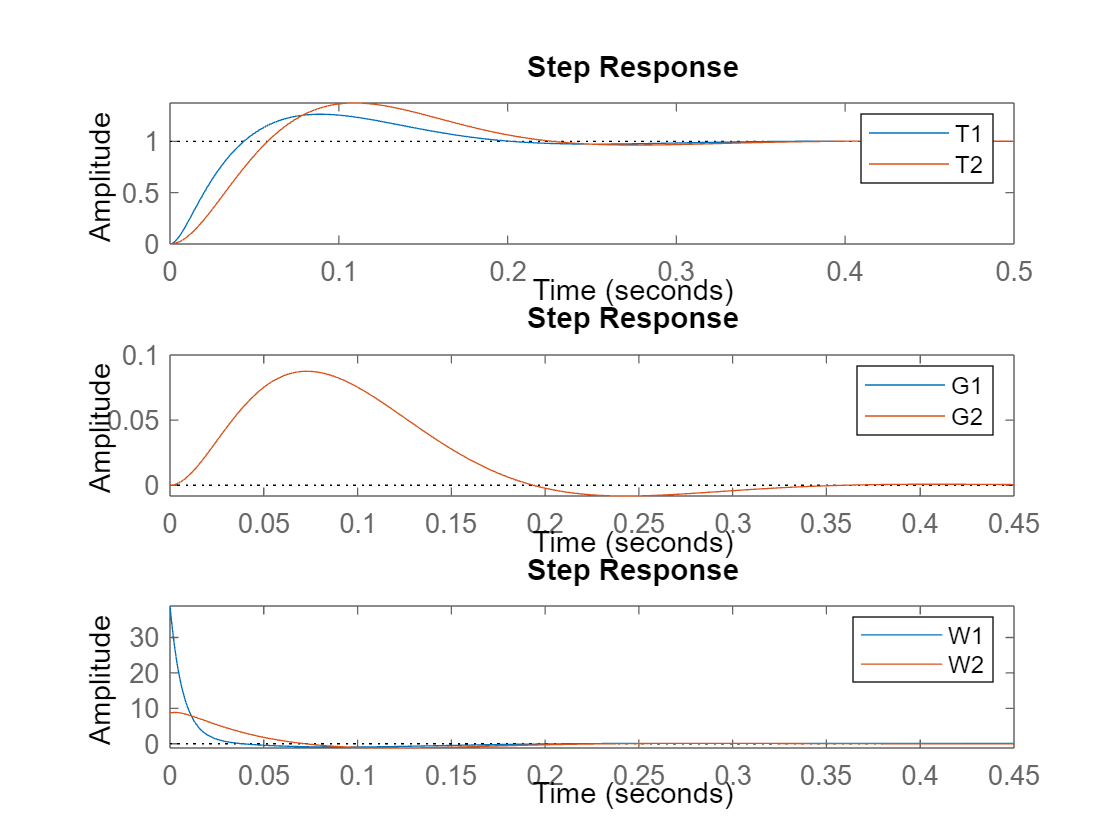

close all
figure(2)
subplot(3, 1, 1)
hold on
step(T1)
step(T2)
legend("T1", "T2")
subplot(3, 1, 2)
hold on
step(G1)
step(G2)
legend("G1", "G2")
subplot(3, 1, 3)
hold on
step(W1)
step(W2)
legend("W1", "W2")

Entrambi gli schemi hanno la stessa funzione di trasferimento tra disturbo e uscita, dunque la capacità di reiezione dei disturbi costanti è la stessa. In particolare, entrambi riescono a regime ad eliminare un disturbo costante. Nel secondo sistema, il riferimento non è derivato e questo comporta un picco minore di tensione richiesto inizialmente.

12.52

## Esercizio 3

clear
close all
clc

s = tf('s');
mot.k = 5.2;
mot.T = 0.03;
P = mot.k / (s * (mot.T * s + 1));
[numP, denP] = tfdata(P, 'v');

pid.Kp = 8.7;
pid.Ki = 120;
pid.Kd = 0.16;
pid.Tl = 0.053;

Ts = 0.005; % [s]
umax = 10; % [V]
res = 500; % [ppr]

rad2deg = 180 / pi;
deg2rad = pi / 180;
pulse2deg = 360 / res;
deg2pulse = res / 360;
rad2pulse = rad2deg * deg2pulse;
pulse2rad = pulse2deg * deg2rad;

sig.A = 360; % [deg]
sig.t = 0.1; % [s]


Discretizzo la componente derivativa del controllore con il metodo di Eulero in avanti, dato che le altre sono direttamente discretizzabili

z = tf('z', Ts);
s1 = (z - 1) / Ts;
Cd = pid.Kd * s1 / (pid.Tl * s1 + 1);
[numCd, denCd] = tfdata(Cd, 'v');


## Simulo il sistema con il risolutore a passo variabile ode45

open_system("ex3_sim1.slx")
set_param("ex3_sim1", "SolverType", "Variable-Step", "Solver", "ode45", "MaxStep", "0.0001", "StopTime", "3");
sim("ex3_sim1")

## Riporto i risultati (13.22 - 13.33)

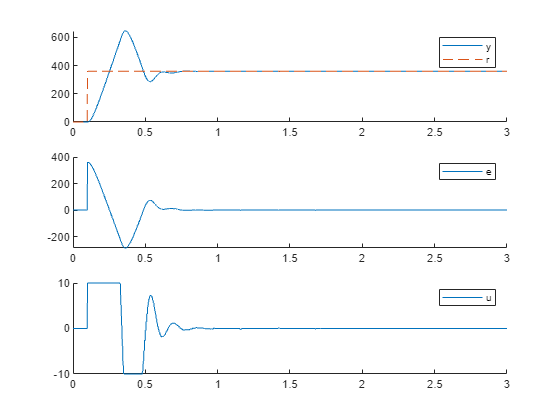

close all

figure(1)
subplot(3, 1, 1)
hold on
plot(sim1_res.time, sim1_res.signals(1).values)
plot(sim1_res.time, sim1_res.signals(2).values, "--")
legend("y", "r")

subplot(3, 1, 2)
hold on
plot(sim1_res.time, sim1_res.signals(3).values)
legend("e")

subplot(3, 1, 3)
hold on
plot(sim1_res.time, sim1_res.signals(4).values)
legend("u")

Si nota come il segnale di tensione presenti periodi di saturazione.

Inserisco uno schema anti-windup

awu.K = 25;

## Simulazione con anti-windup

open_system("ex3_sim2.slx")
set_param("ex3_sim2", "SolverType", "Variable-Step", "Solver", "ode45", "MaxStep", "0.0001", "StopTime", "3");
sim("ex3_sim2")


## Riporto i risultati (13.22 - 13.33)

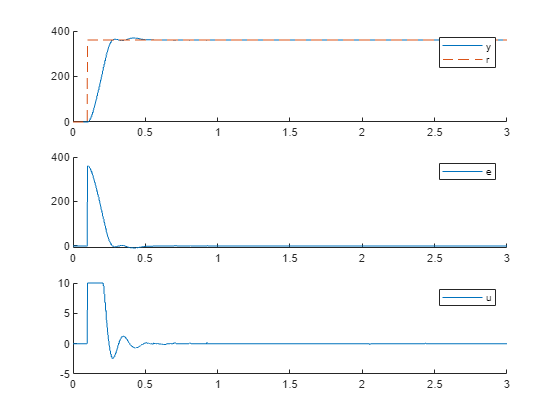

close all

figure(1)
subplot(3, 1, 1)
hold on
plot(sim2_res.time, sim2_res.signals(1).values)
plot(sim2_res.time, sim2_res.signals(2).values, "--")
legend("y", "r")

subplot(3, 1, 2)
hold on
plot(sim2_res.time, sim2_res.signals(3).values)
legend("e")

subplot(3, 1, 3)
hold on
plot(sim2_res.time, sim2_res.signals(4).values)
legend("u")

L'anti-windup permette di ridurre il periodo di tempo in cui il controllore è in saturazione e riduce l'overshoot.

## Overshoot

L'overshoot nei due casi è

info1 = stepinfo(sim1_res.signals(1).values, sim1_res.time);
info2 = stepinfo(sim2_res.signals(1).values, sim1_res.time);
info1.Overshoot

ans = 79.4000

info2.Overshoot

ans = 2.6000